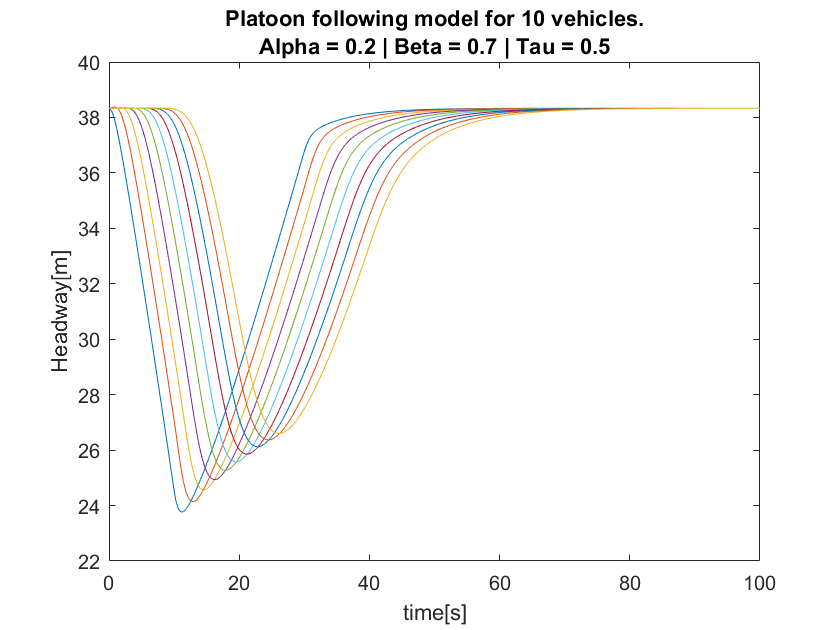


clear all; close all;

follow_num = 10;
tau = 0.5;

alpha = 0.2;
beta = 0.7;
kappa = 0.6;


vmax = 30;
vstar = 20;
a = 1;
b = 0.5;
hstop = 5;
hgo = hstop + vmax/kappa;
hstar = vstar/kappa + hstop;

tstart = 0;
tdelta = 0.1;
tend = 100;
tspan = tstart:tdelta:tend;

h0 = hstar*ones(follow_num,1); %Here assuming that all vehicles start with vstar velocity and with hstar headway
v0 = vstar*ones(follow_num,1);
ic = @(t)[h0  v0];


sol = dde23(@(t,y,ytau)ddefun(t,y,ytau,follow_num,alpha,beta,kappa,vstar,a,b,vmax,hstop,hgo,tau),tau,ic,tspan);
y = deval(sol,tspan);

headways = y(1:follow_num,:);
velocities = y(follow_num+1:2*follow_num,:);

figure(1);
plot(tspan,headways);
xlabel('time[s]');
ylabel('Headway[m]');
title({"Platoon following model for "+follow_num+...
    " vehicles.", "Alpha = "+alpha+" | Beta = "+beta+" | Tau = "+tau});

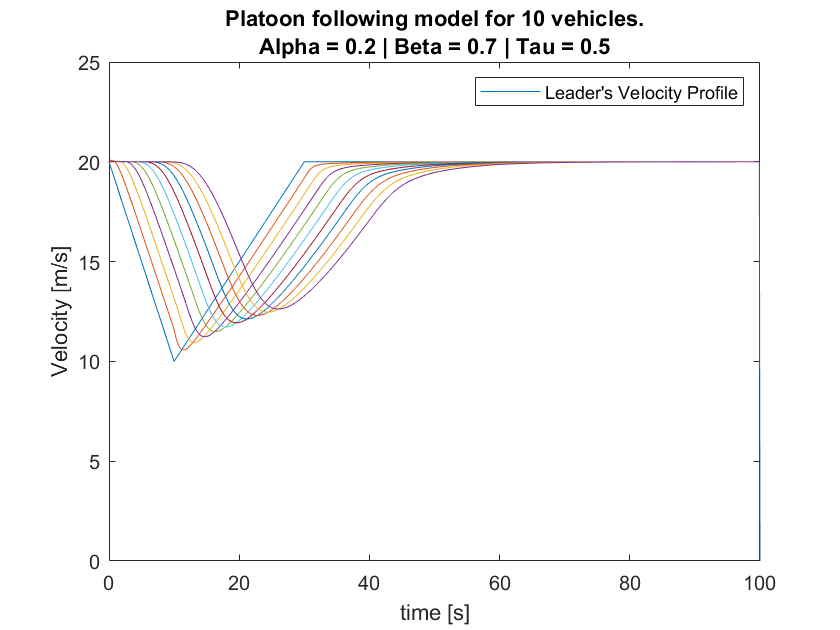


figure(2);
plot(tspan,vlead_func(tspan,vstar,a,b)); %Can change the leader velocity to any required...
%profile from the function below 
hold on;
plot(tspan,velocities);
xlabel('time [s]');
ylabel('Velocity [m/s]');
title({"Platoon following model for "+follow_num+...
    " vehicles.","Alpha = "+alpha+" | Beta = "+beta+" | Tau = "+tau});
legend('Leader''s Velocity Profile');

function dydt = ddefun(t,y,ytau,follow_num,alpha,beta,kappa,vstar,a,b,vmax,hstop,hgo,tau)
   
    
    h = y(1:follow_num);
    vF = y(follow_num+1:end);
    vL = [vlead_func(t,vstar,a,b);
      vF(1:follow_num-1)] ; 
  
    htau = ytau(1:follow_num);
    vFtau = ytau(follow_num+1:end);
    vLtau = [vlead_func_delayed(t,vstar,a,b,tau);
          vFtau(1:follow_num-1)] ;
  
    %Range Policy
    Vh = 0 + ((hstop<h)&(h<hgo)).*(kappa.*(h-hstop)) + (h>=hgo).*(vmax);
    Vhtau = 0 + ((hstop<h)&(h<hgo)).*(kappa.*(htau-hstop)) + (h>=hgo).*(vmax);
    
    dydt = [(vL-vF);alpha.*(Vhtau-vF)+beta.*(vLtau-vFtau)];
end



function vl = vlead_func(t,vstar,a,b)
%Velocity profile fron HW2 Q1
t1 = 10;
t2 = 30;
t3 = 100;
    vl = ((0<=t)&(t<t1)).*(vstar - a.*t) +...
         ((t1<=t)&(t<t2)).*(vstar + b.*(t-t2)) +...
         ((t2<=t)&(t<t3)).*vstar;      

%   vl =15+ 6*cos(t);

% %Velocity profile from HW6 Q2. Deceleration of -10[m/s2]. Although
% % acceleration feedback here. Velocity profile is taken from HW6 just to
% % compare the results.
% t1 = 1.5; %Stopping time taken from HW6.
% vl_acc = 10;    
% vl=(vstar-vl_acc*t).*(t<=t1);
end

function vl = vlead_func_delayed(t,vstar,a,b,tau)
%Velocity profile fron HW2 Q1
t1 = 10;
t2 = 30;
t3 = 100;
    vl = ((0<=t)&(t<t1)).*(vstar - a.*(t-tau)) +...
         ((t1<=t)&(t<t2)).*(vstar + b.*((t-tau)-t2)) +...
         ((t2<=t)&(t<t3)).*vstar;      

%   vl =15+ 6*cos(t);

% %Velocity profile from HW6 Q2. Deceleration of -10[m/s2]. Although
% % acceleration feedback here. Velocity profile is taken from HW6 just to
% % compare the results.
% t1 = 1.5; %Stopping time taken from HW6.
% vl_acc = 10;    
% vl=(vstar-vl_acc*t).*(t<=t1);
end
